# Expand Example 3.33:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the trapezoidal spectrum given below:

        
$$X(f)=\left\{\begin{array}{c l}
    1\;, &\quad \left|f\right| \le f_{0}\left(1-r\right)  \\
    \frac{1}{2r}\,
    \left[-\frac{\left|f\right|}{f_{0}}+1+r\right]\;,
    &\quad
    f_{0}\left(1-r\right)<\left|f\right|\le f_{0}\left(1+r\right) \\
    0\;, &\quad\left|f\right|>f_{0}\left(1+r\right)
  \end{array}
  \right.$$


The signal that corresponds to this spectrum is

        
$$x(t) = 2f_{0}\,\textrm{sinc}(2f_{0}\,t)\,\textrm{sinc}(2f_{0}\,rt)
$$


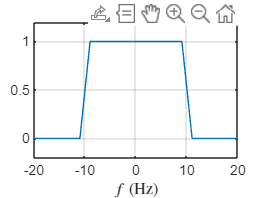

f0 = 10;  % Frequency
r =  0.1; % Roll-off factor
%
f = [-20:0.05:20];
% Compute the trapezoidal spectrum X(f)
X1 = 1.*((f>=-f0*(1-r))&(f<=f0*(1-r)));
X2 = 1/(2*r)*(-abs(f)/f0+1+r).*((abs(f)>f0*(1-r))&(abs(f)<f0*(1+r)));
X = X1+X2;
t = [-0.5:0.001:0.5];  % Vector of time instants
% Compute the inverse transform x(t)
x = 2*f0*sinc(2*f0*t).*sinc(2*f0*r*t);
plot(f,X); grid;
axis([-20,20,-0.2,1.2]);
set(0,'defaultTextInterpreter','latex');
xlabel('$f$ (Hz)');
title('$X(f)$');

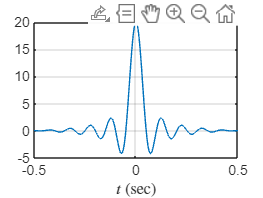

plot(t,x); grid;
xlabel('$t$ (sec)');
title('$x(t)$');

set(0,'defaultTextInterpreter','tex');